# Initialize

clear all;
gamma = 5/3;
kUpLimit = -0.001;
kx1 = kUpLimit:-0.001:-2;
theta = 0:0.1:89.9;
for i = 1:1:length(theta)
    omega(i,:,:)= solve_wave_dispersion_theta(kx1,theta(i),gamma);
end


## Plotting

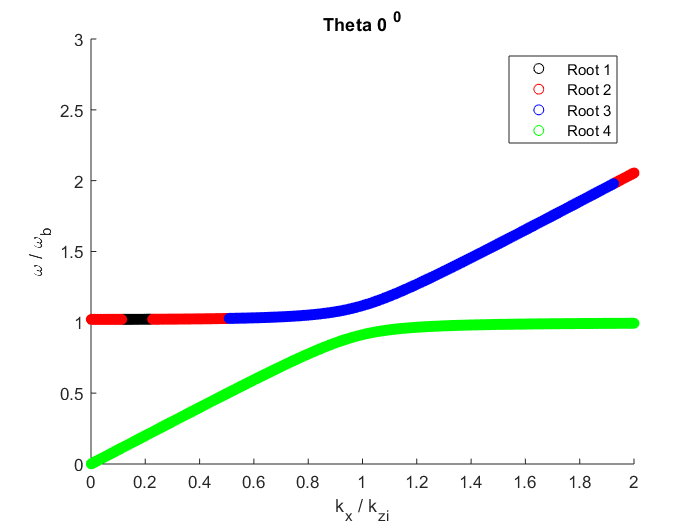

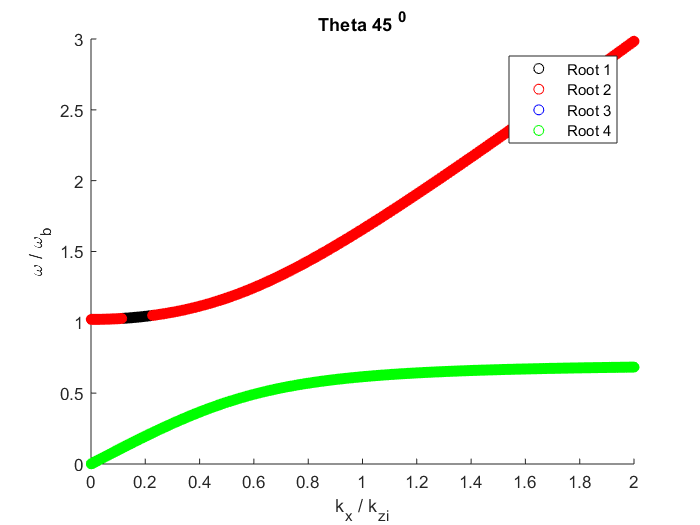

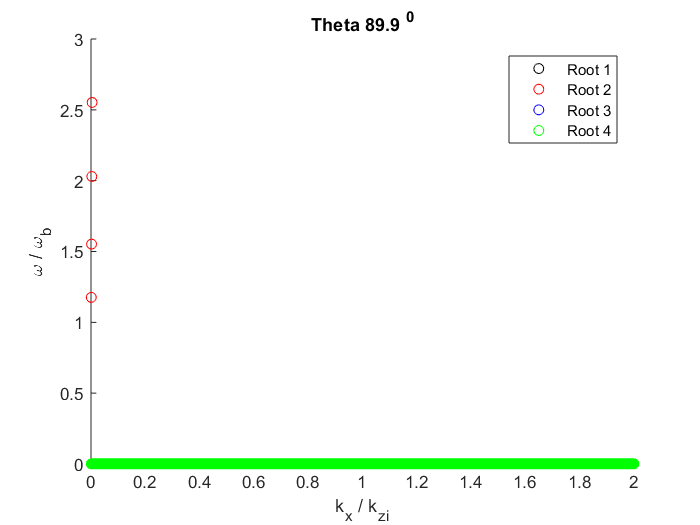

% Chose what to plot
thetaArray = [0,45,89.9];
for i = 1:1:length(thetaArray)
    thisTheta = thetaArray(i);
    thisThetaIndx = round(interp1(theta,1:1:length(theta),thisTheta));
    
    figure;
    thisRoot(1) = 1;
    a=scatter(-kx1,squeeze(omega(thisThetaIndx,:,thisRoot(1))),'k');
    hold on;
    thisRoot(2) = 2;
    b=scatter(-kx1,squeeze(omega(thisThetaIndx,:,thisRoot(2))),'r');
    hold on;
    thisRoot(3) = 3;
    c=scatter(-kx1,squeeze(omega(thisThetaIndx,:,thisRoot(3))),'b');
    hold on;
    thisRoot(4) = 4;
    d=scatter(-kx1,squeeze(omega(thisThetaIndx,:,thisRoot(4))),'g');
    hold on;
    xlabel('k_x / k_z_i');
    ylabel('\omega / \omega_b');
    legend(['Root ',num2str(1)],['Root ',num2str(2)],['Root ',num2str(3)],['Root ',num2str(4)])
    title(['Theta ',num2str(thisTheta),' ^0']);
    ylim([0 3]);
end


% ylim([0 2]);



## MSIS

m = 28.9 * 1.67*10^-27; %kg
kb = 1.38064852 * 10^-23; %  m2 kg s-2 K-1
g0 =  9.80665 ; % m/s^2
re = 6.3781 *10^6; % m
time = datenum('21 Aug 2017 8:00');
lat = 40;
lon = -100;
altitude = 1:0.1:300;

[Density, Temperature] = msis(time,lat,lon,altitude);
  
  coordinateSystem = 'geodetic';
  curlDir='C:\Users\Nithin\Documents\GitHub\energy-height-conversion\Tools\External Tools';
altIndxMinIRI = interp1(altitude,1:1:length(altitude),60);
altitudeIRI = altitude(altIndxMinIRI:1:end);
IRI=iri2012(time,lat,lon,altitudeIRI, true, coordinateSystem,curlDir, [], [], [], [], [], [], [], [], [], [] ,[] ,[], [], [], 'RBV10/TTS03' );
Ni=IRI(:,1)';
Nn = Density(:,4)'./m;
TN = Temperature(:,1);
cs = (gamma.*kb.*TN./m).^0.5;
g = (g0.*(re./(re+altitude*1000)).^2)';


## Plot & Check MSIS & IRI

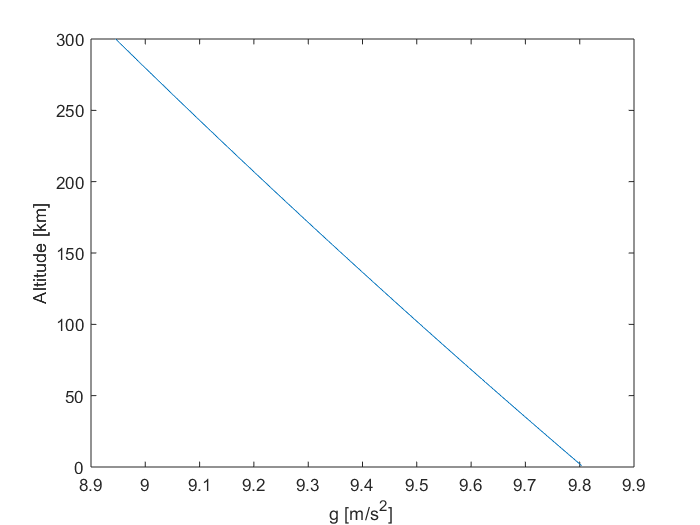

figure;
plot(g,altitude); xlabel('g [m/s^2]'); ylabel('Altitude [km]');

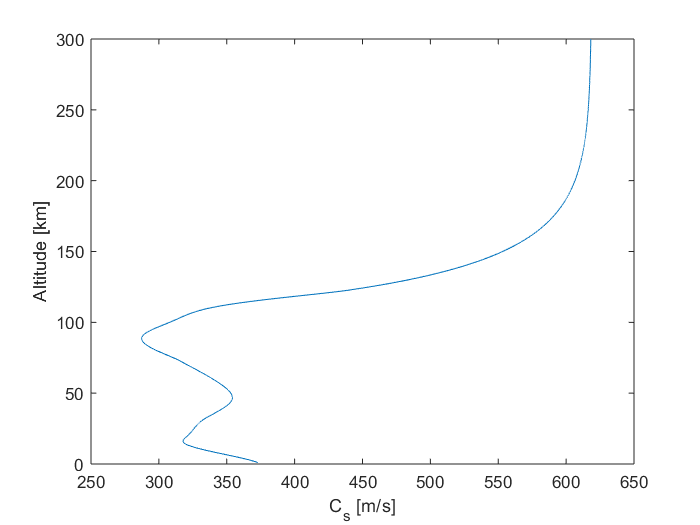

figure;
plot(cs,altitude); xlabel('C_s [m/s]'); ylabel('Altitude [km]');

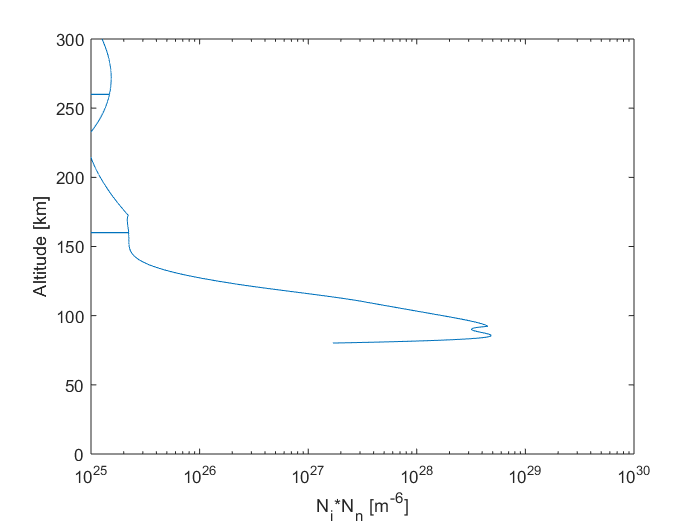

figure;
semilogx(Ni.*Nn(altIndxMinIRI:1:end),altitudeIRI);xlabel('N_i*N_n [m^-^6]'); ylabel('Altitude [km]'); ylim([0 300]); xlim([10^25 10^30]);

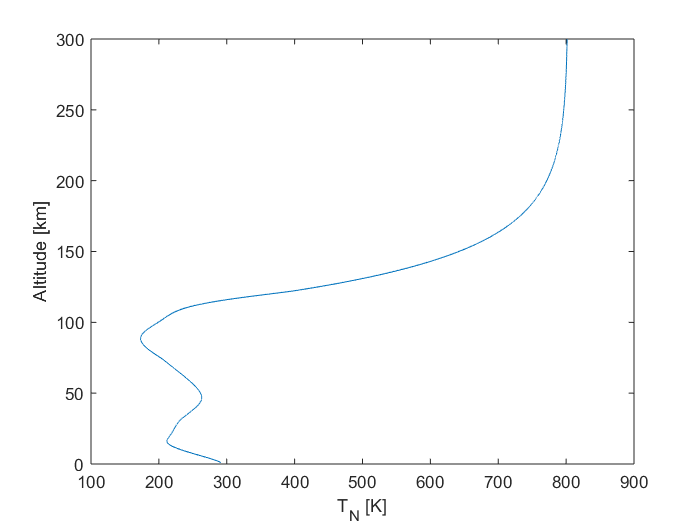

figure;
plot(TN,altitude); xlabel('T_N [K]'); ylabel('Altitude [km]');

## Calculating w and k

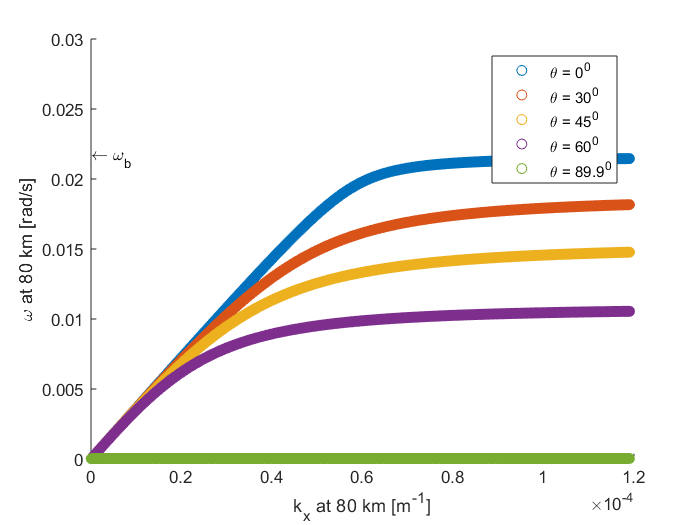

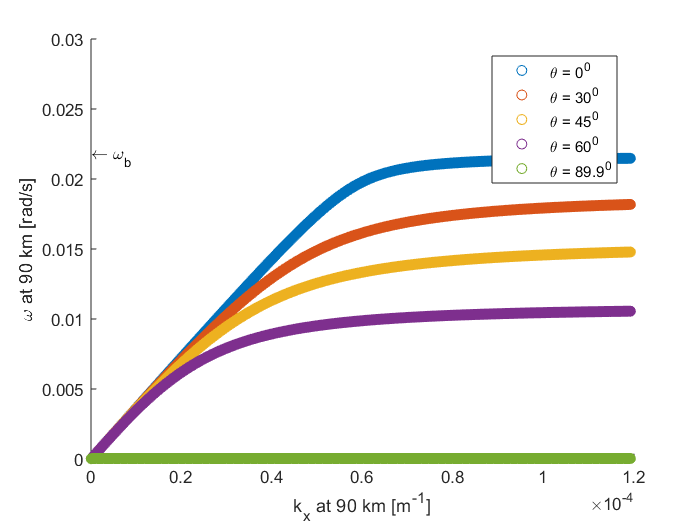

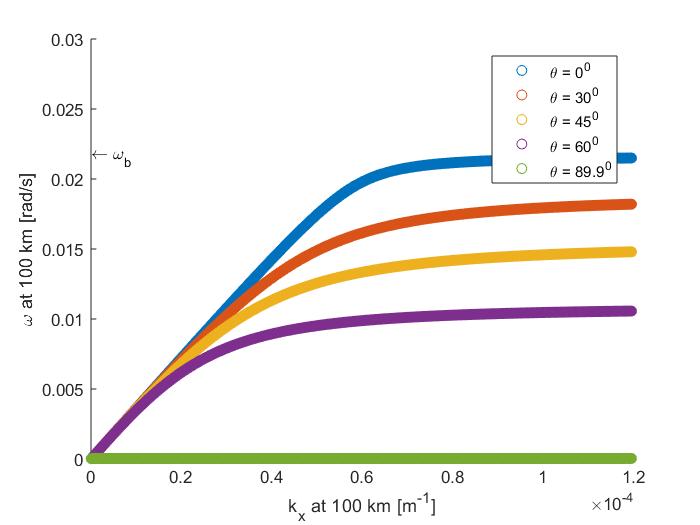

alt=[80,90,100];
thisRoot = 4;
for i = 1:3
    thisAlt = alt(i);
    kzi = -gamma.*g./(2.*cs.^2);
    wb = (((gamma-1).*g.^2)./(cs.^2)).^0.5;
    thisTheta = [0,30,45,60,89.9];
    thisThetaIndx = round(interp1(theta,1:1:length(theta),thisTheta));
    thisAltIndx = round(interp1(1:1:length(altitude),altitude,thisAlt));
    for j=1:1:length(thisTheta)
        w(j,:) = squeeze(omega(thisThetaIndx(j),:,thisRoot)).*wb(thisAltIndx);
    end
    kx = kx1.*kzi(thisAltIndx);
%     kzr = kx.*tand(thisTheta);
    
    figure;
    for j=1:1:length(thisTheta)
        scatter(kx,w(j,:),'o');
        legendStr(1,j)={['\theta = ',num2str(thisTheta(j)),'^0']};
        hold on;
    end
    legend (legendStr);
    hold on;
    text(min(kx),wb(thisAltIndx),'\leftarrow \omega_b');
    wb(thisAltIndx);
    % line(k_horizontal_1,wb(altIndx)*ones(length(k_horizontal_1)));
    ylim([0 0.03]);
    ylabel(['\omega at ',num2str(thisAlt),' km [rad/s]']);
    xlabel(['k_x at ',num2str(thisAlt),' km [m^-^1]']);
end

## Calculating k variation given an w and theta

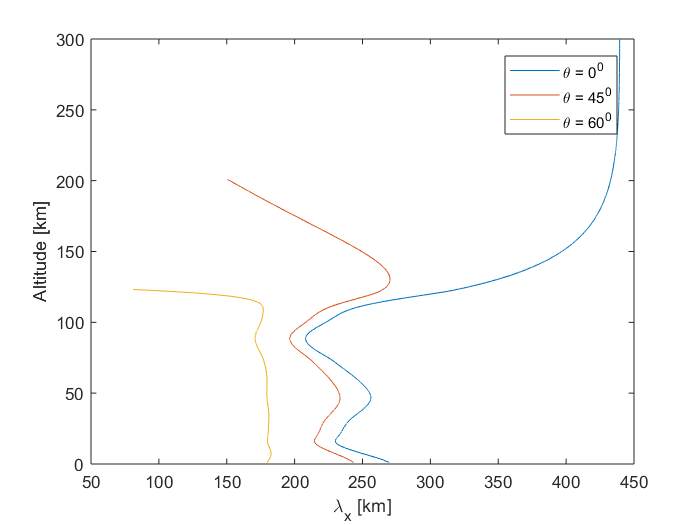

f = 1.35*10^-3; %1 mHz
w_given = 2*pi*f;
thisRoot = 4;
kzi = -gamma.*g./(2.*cs.^2);
wb = (((gamma-1).*g.^2)./(cs.^2)).^0.5;
thisTheta = [0,45,60];    
thisThetaIndx = round(interp1(theta,1:1:length(theta),thisTheta));
for i=1:1:length(altitude)
    thisAlt=altitude(i);
    thisAltIndx = interp1(altitude,1:1:length(altitude),thisAlt);
    for j=1:1:length(thisTheta)
        k_horiz(i,j) = interp1(squeeze(omega(thisThetaIndx(j),:,thisRoot)).*wb(thisAltIndx),kx1.*kzi(thisAltIndx),w_given);
    end
end

figure;
lambda = 2*pi./k_horiz;
plot(lambda(:,1)/1000,altitude);
hold on;
plot(lambda(:,2)/1000,altitude);
hold on;
plot(lambda(:,3)/1000,altitude);
xlabel('\lambda_x [km]');
ylabel('Altitude [km]');
legend (['\theta = ',num2str(thisTheta(1)),'^0'],['\theta = ',num2str(thisTheta(2)),'^0'], ['\theta = ',num2str(thisTheta(3)),'^0']);

## Calculating theta, given kx and w

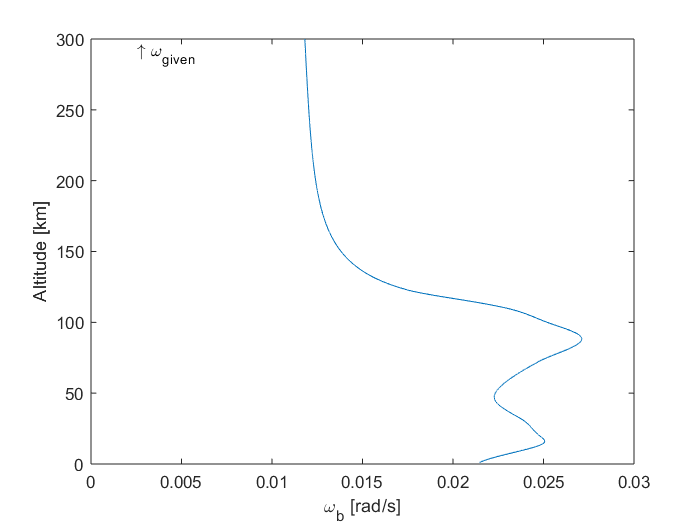

% f = 0.8*10^-3; %1 mHz
f = 1/(40.8*60);
lambda_x = 182.4*1000; % 200 km
w_given = 2*pi*f;

wb = (((gamma-1).*g.^2)./(cs.^2)).^0.5;
figure;
plot(wb,altitude); xlabel('\omega_b [rad/s]'); ylabel('Altitude [km]');
xlim([0 0.03]);
text(w_given,max(altitude)-10,'\uparrow \omega_g_i_v_e_n');

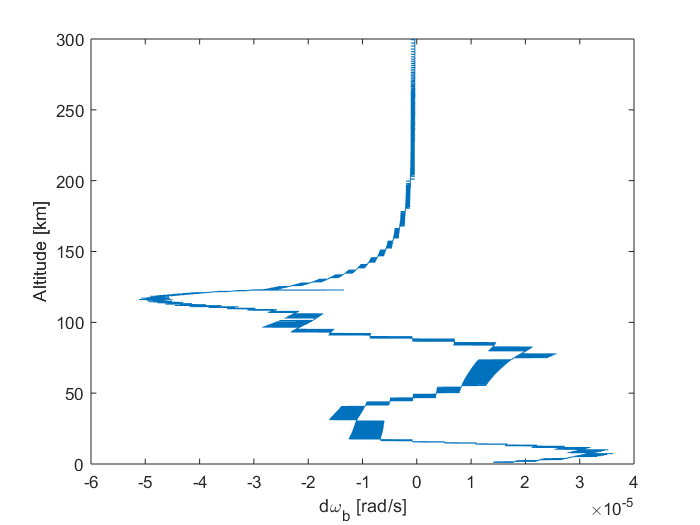

figure;
plot(diff(wb),altitude(1:end-1)); xlabel('d\omega_b [rad/s]'); ylabel('Altitude [km]');

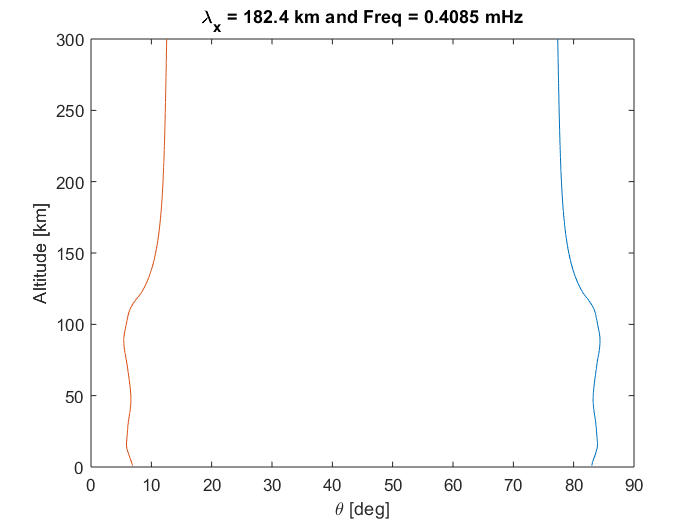


kx_given = 2*pi/lambda_x;
thisRoot = 4;
kzi = -gamma.*g./(2.*cs.^2);
wb = (((gamma-1).*g.^2)./(cs.^2)).^0.5;
for i=1:1:length(altitude)
    thisAlt=altitude(i);
    thisAltIndx = round(interp1(altitude,1:1:length(altitude),thisAlt));
    thisKxIndx = round(interp1(kx1.*kzi(thisAltIndx),1:1:length(kx1),kx_given));
    thetaCalculated(i,1) = interp1(squeeze(omega(:,thisKxIndx,thisRoot)).*wb(thisAltIndx),theta,w_given);  
end

figure;
plot(thetaCalculated,altitude);

thetaAzeem2017 = asin(w_given./wb);
hold on; plot(rad2deg(thetaAzeem2017),altitude);
xlabel('\theta [deg]');
ylabel('Altitude [km]');
title(['\lambda_x = ',num2str(lambda_x/1000),' km and Freq = ',num2str(f*1000),' mHz']);
xlim([0 90]);
ylim([0 300]);

## Calculating cut-off frequency vs. altitude per angle

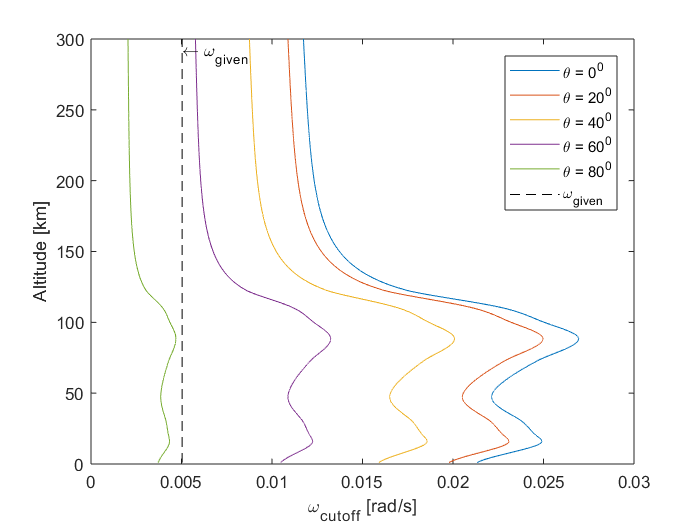

thisRoot = 4;

for i=1:1:length(theta)
    w_cutoff(i,:) = max(omega(i,:,thisRoot)).*wb;
end
figure;
j=1;
for i=1:200:length(theta)
    plot(w_cutoff(i,:),altitude);
    hold on;
    legendStr1(1,j)={['\theta = ',num2str(theta(i)),'^0']};
    j=j+1;
end
    xlim([0 0.03]);
    xlabel(['\omega_c_u_t_o_f_f [rad/s]']);
    ylabel(['Altitude [km]']);
    line([w_given w_given],[min(altitude) max(altitude)],'color','k','LineStyle','--');
    legendStr1(1,j)={'\omega_g_i_v_e_n'};
    legend(legendStr1);
    text(w_given,max(altitude)-10,'\leftarrow \omega_g_i_v_e_n');

## W associated for a particular k, for each theta

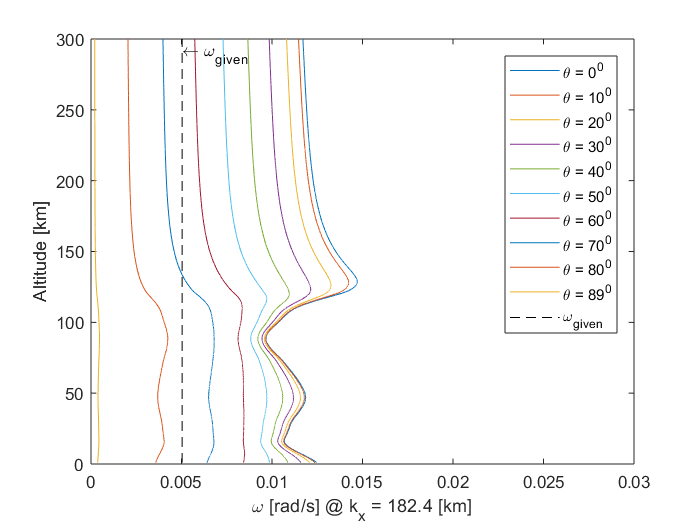

thisRoot = 4;
figure;
j=1;
thisTheta=[0,10,20,30,40,50,60,70,80,89];
for i=1:1:length(thisTheta)
    for k=1:1:length(altitude)
       thisAlt=altitude(k);
       thisAltIndx = interp1(altitude,1:1:length(altitude),thisAlt);
       thisKxIndx = round(interp1(kx1.*kzi(thisAltIndx),1:1:length(kx1),kx_given));
       thisThetaIndx = round(interp1(theta,1:1:length(theta),thisTheta(i)));
       w_given_k(i,k) = (omega(thisThetaIndx,thisKxIndx,thisRoot)).*wb(thisAltIndx);
    end
    plot(w_given_k(i,:),altitude);
    hold on;
    legendStr1(1,j)={['\theta = ',num2str(thisTheta(i)),'^0']};
    j=j+1;
end
    xlim([0 0.03]);
    xlabel(['\omega [rad/s] @ k_x = ',num2str(lambda_x/1000),' [km]']);
    ylabel(['Altitude [km]']);
    line([w_given w_given],[min(altitude) max(altitude)],'color','k','LineStyle','--');
    legendStr1(1,j)={'\omega_g_i_v_e_n'};
    legend(legendStr1);
    text(w_given,max(altitude)-10,'\leftarrow \omega_g_i_v_e_n');

**Functions **

function w=solve_wave_dispersion(kx,kzr,gamma)
    alpha = (gamma.^2)./(4*(gamma-1));
    n_kx = length(kx);
    n_kzr = length(kzr);
    for i = 1:1:n_kx
        for j = 1:1:n_kzr
            w(i,j,:) =...
                roots([1,... %w4
                       0,... %w3
                       -alpha.*(kx(i).^2+kzr(j).^2+1),... %w2
                       0,... %w1
                       alpha.*kx(i).^2]); %w0
        end
    end
  
end

function w=solve_wave_dispersion_theta(kx,theta,gamma)
    alpha = (gamma.^2)./(4*(gamma-1));
    n_kx = length(kx);
    kzr = (tand(theta))*kx;

    for i = 1:1:n_kx
           w(i,:) =...
                roots([1,... %w4
                       0,... %w3
                       -alpha.*(kx(i).^2+kzr(i).^2+1),... %w2
                       0,... %w1
                       alpha.*kx(i).^2]); %w0
    end
  
end

